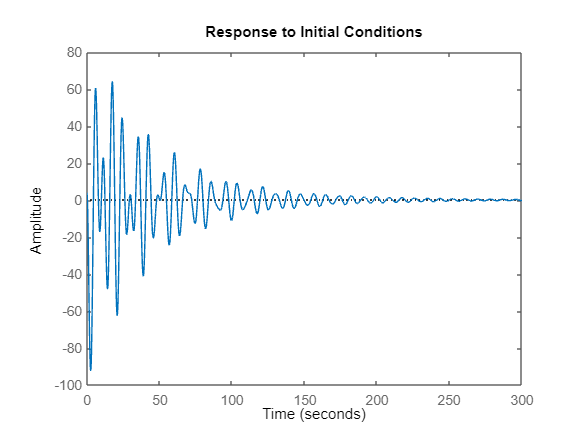


%Defining our matrices as follows
A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
% Cosidering the same Q and R matrices chosen before in our code
Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.001; %these are the cost variables from LQR
% From previous case, we have determined that only C1, C3 and C4 were
% observable. Hence, we are going to consider only those 3 cases.
C1 = [1 0 0 0 0 0];  %Corresponding to x component
C3 = [1 0 0 0 0 0; 0 0 0 0 1 0]; %corresponding to x and theat2
C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; %corresponding to x, theta1 and theat2
D = 0; 
% Initial Conditions for Leunberger observer - 12 state variables, 
% 6 actual + 6 estimates
x0 = [4;0;30;0;60;0;0;0;0;0;0;0];
% Calling LQR function to obtain K matrix
K =lqr(A,B,Q,R);
vd=0.3*eye(6); %process noise
vn=1; %measurement noise

K_pop1=lqr(A',C1',vd,vn)'; %gain matrix of kalman filter for C1
K_pop3=lqr(A',C3',vd,vn)'; %gain matrix of kalman filter for C3
K_pop4=lqr(A',C4',vd,vn)'; %gain matrix of kalman filter for C4

% Observing state space corresponding C1 observable system
sys1 = ss([(A-B*K) B*K; zeros(size(A)) (A-K_pop1*C1)], [B;zeros(size(B))],[C1 zeros(size(C1))], D);
figure
initial(sys1,x0)

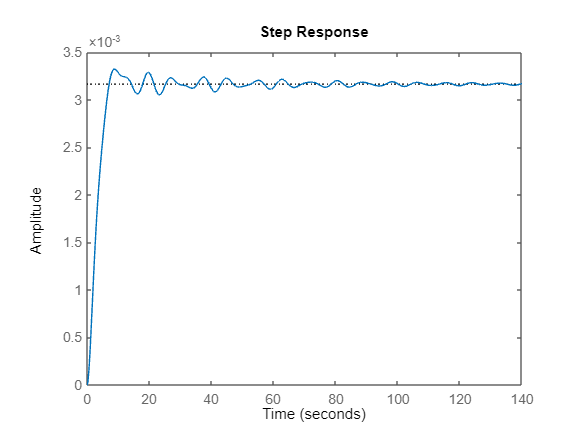

figure
step(sys1)

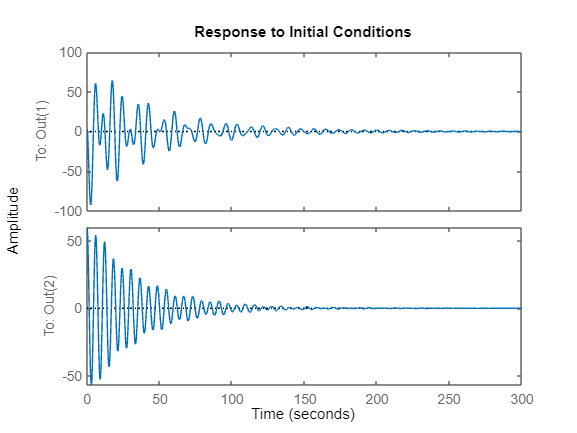


% Observing state space corresponding C3 observable system 
sys3 = ss([(A-B*K) B*K; zeros(size(A)) (A-K_pop3*C3)], [B;zeros(size(B))],[C3 zeros(size(C3))], D);
figure
initial(sys3,x0)

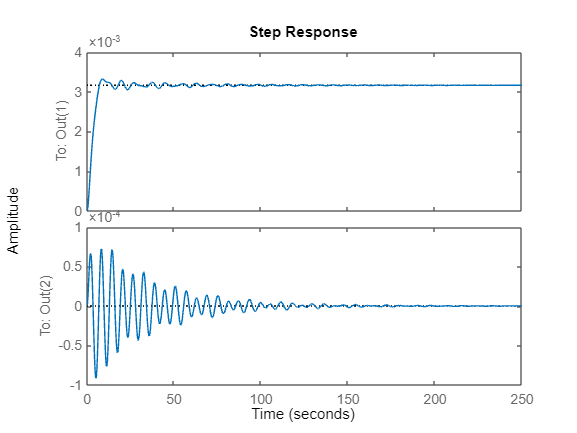

figure
step(sys3)

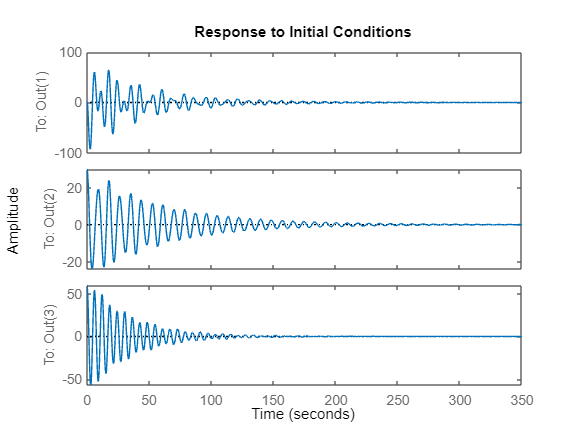


% Observing state space corresponding C4 observable system 
sys4 = ss([(A-B*K) B*K; zeros(size(A)) (A-K_pop4*C4)], [B;zeros(size(B))],[C4 zeros(size(C4))], D);
figure
initial(sys4,x0)

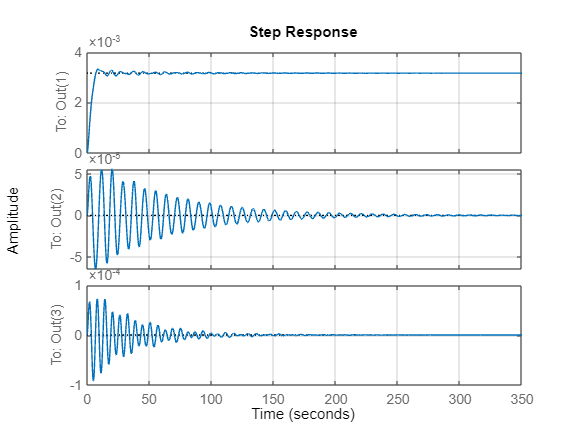

figure
step(sys4)

grid on